# SVM classification: EEG data Analysis_#3

clc; 
clear; 
close all; 

#### Load Data

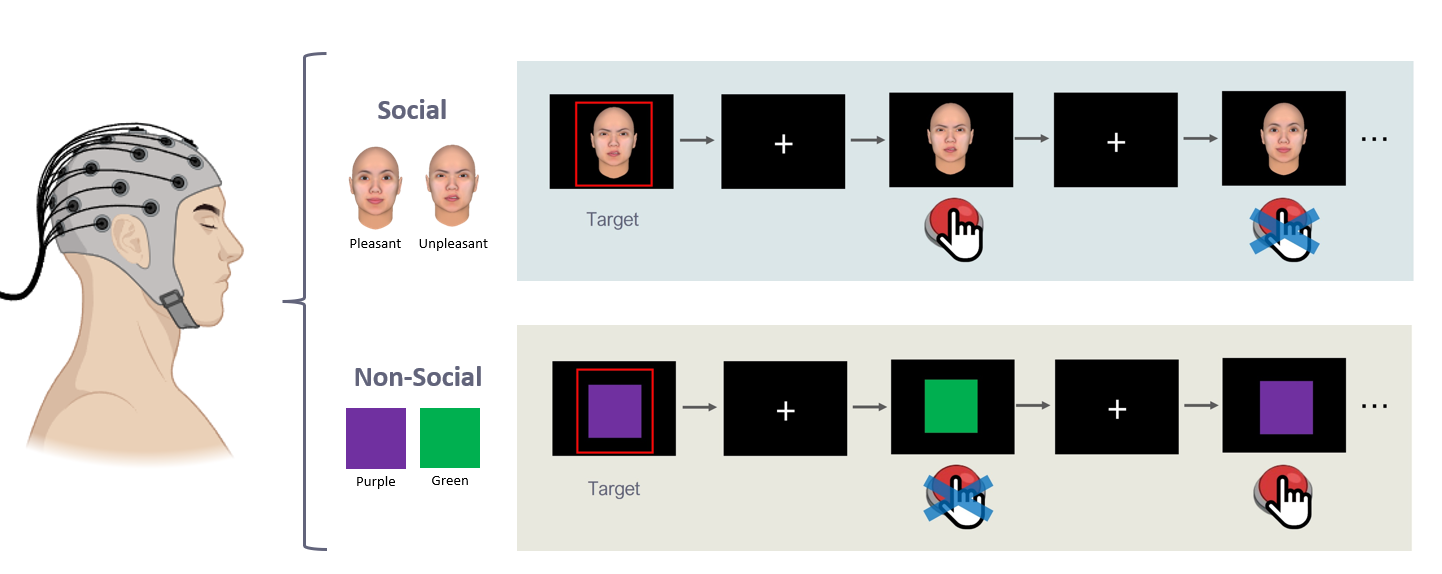

data = importdata('data_eeg.mat')

data = 다음 필드를 포함한 1×10 struct 배열:
    eeg
    IsPatients
    eventlabel
    eventstamp
    fs


### Data Information

ChanName = {'Fp1', 'Fpz', 'Fp2','F7','F3','Fz','F4','F8','FC9','FC5','FC1', ...
    'FC2','FC6','FC10','T7','C3','Cz','C4','T8','CP5','CP1','CP2','CP6', ...
    'P7','P3','Pz','P4','P8','O1','Oz','O2'};

nsubj = length(data)

nsubj = 10

fs = data(1).fs

fs = 500

nch = size(data(1).eeg, 1)

nch = 31

% time information
time_window = [-0.2 1.0];
time = time_window(1):1/fs:time_window(2); time(1) = [];

### Raw Data Processing

% Data Processing 
EEG_TD = []; EEG_ADHD = []; 
EEG_Total = []; 

for i = 1:length(data)
    % TD
    if data(i).IsPatients == 0
        EEG_TD = cat(3, EEG_TD, data(i).eeg);
    % ADHD
    elseif data(i).IsPatients == 1
        EEG_ADHD = cat(3, EEG_ADHD, data(i).eeg);
    end
end

EEG_Total = cat(3, EEG_TD, EEG_ADHD);

### Averaged Data Processing and Visualization

% Number of trials to average (5-Trial Average)
group_size = 5;

% Initialize matrices to store the final averaged data
EEG_TD_A = []; EEG_ADHD_A = []; EEG_Total_A = [];

% (1) Process TD data
n_TD_groups = floor(size(EEG_TD, 3) / group_size);

for j = 1:n_TD_groups
    group_indices = (j-1)*group_size + 1 : j*group_size;
    averaged_trial = mean(EEG_TD(:, :, group_indices), 3);
    EEG_TD_A = cat(3, EEG_TD_A, averaged_trial);
end

disp(['Size of EEG_TD_A: ', mat2str(size(EEG_TD_A))]);

Size of EEG_TD_A: [31 600 200]


% (2) Process ADHD data
n_ADHD_groups = floor(size(EEG_ADHD, 3) / group_size);

for j = 1:n_ADHD_groups
    group_indices = (j-1)*group_size + 1 : j*group_size;
    averaged_trial = mean(EEG_ADHD(:, :, group_indices), 3);
    EEG_ADHD_A = cat(3, EEG_ADHD_A, averaged_trial);
end

disp(['Size of EEG_ADHD_A: ', mat2str(size(EEG_ADHD_A))]);

Size of EEG_ADHD_A: [31 600 200]


% (3) Process the total averaged data
EEG_Total_A = cat(3, EEG_TD_A, EEG_ADHD_A);

disp(['Size of EEG_Total_A: ', mat2str(size(EEG_Total_A))]);

Size of EEG_Total_A: [31 600 400]


**Visualization**

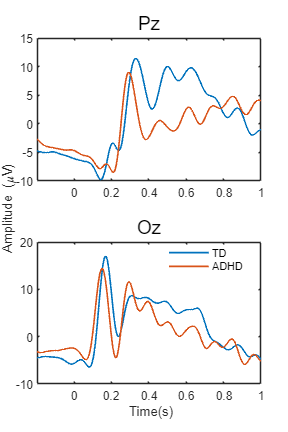

ch_idx = [26 30]; % Pz, Oz

figure('Position', [400 40 400 600]);
tiledlayout(2,1);
for ich = ch_idx
    nexttile();

    plt(1) = plot(time, mean(EEG_TD_A(ich, :, :), 3), 'LineWidth', 1.2);
    hold on;
    plt(2) = plot(time, mean(EEG_ADHD_A(ich, :, :), 3), 'LineWidth', 1.2);
    title(ChanName{ich}, 'FontSize', 14);

end

% legend options
legend(plt, {'TD', 'ADHD'}, 'Location', 'best', 'box', 'off')

% figure options
ax = axes('Visible', 'off');
ax.XLabel.Visible = 'on';
ax.YLabel.Visible = 'on';
xlabel('Time(s)');
ylabel('Amplitude (\muV)');

### SVM Classification (Averaged Data)

**Data Setting**

% Select the desired time segment
timeidx = time> 0.1 & time <= 0.4;

EEG_Total_A_selected = EEG_Total_A(:, timeidx, :);

num_samples = size(EEG_Total_A_selected, 3); % Number of samples in averaged data
disp(['Size of EEG_Total_A_selected: ', mat2str(size(EEG_Total_A_selected))]);

Size of EEG_Total_A_selected: [31 150 400]


% Prepare labels for both datasets
labels = [zeros(size(EEG_TD_A, 3), 1); ones(size(EEG_ADHD_A, 3), 1)];

% Reshape EEG data to be suitable for SVM input
% Flatten each trial to create a 2D feature matrix: [samples x features]
features = reshape(EEG_Total_A_selected, [], num_samples)';
size(features)

ans =          400        4650


% Split into training and testing sets (80-20 split)
rng(1); % Set a fixed random seed for reproducibility
cv = cvpartition(labels, 'HoldOut', 0.2);
train_idx = training(cv);
test_idx = test(cv);

#### `!!!Fill the blank!!!`

% Set Training and test data
X_train = features(train_idx, :);
X_test = features(test_idx, :);

Y_train = labels(train_idx);
Y_test = labels(test_idx);

**SVM**

#### `!!!Fill the blank!!!`

% Train SVM
svm_model = fitcsvm(X_train, Y_train, 'KernelFunction', 'linear', 'Standardize', true);
Y_pred = predict(svm_model, X_test);
accuracy = mean(Y_pred == Y_test) * 100;

disp(['Accuracy with averaged data: ', num2str(accuracy), '%']);

Accuracy with averaged data: 90%


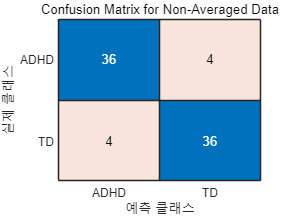

% Confusion Matrix
conf_mat = confusionmat(Y_test, Y_pred);
figure;
confusionchart(conf_mat, {'TD', 'ADHD'});
title('Confusion Matrix for Non-Averaged Data');

### Key Feature Visualization and t-SNE (Averaged Data)

**Weight Calculation**

#### `!!!Fill the blank!!!`

weight = svm_model.Beta;

top10N = round(size(X_train, 2) * 0.10);
[M,I] = sort(weight, 'descend');
topWeight = nan(size(weight));
topWeight(I(1:top10N)) = weight(I(1:top10N));
topWeight = reshape(topWeight, nch, []);

**Visualization**

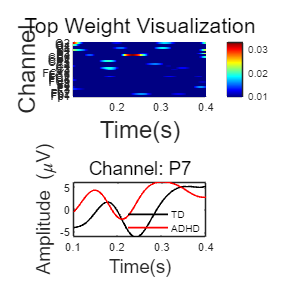

% Create a single figure window with two plots using tiledlayout
figure('Position', [400, 40, 800, 800]);
tiledlayout(2, 1);

% Plot 1: Weight Visualization for Averaged SVM Model
nexttile;
im = imagesc('XData', time(timeidx), 'YData', [1:nch], 'CData', topWeight);
xlim('tight'); ylim('tight');
colormap(jet)
xlabel('Time(s)', 'FontSize', 18);
ylabel('Channel', 'FontSize', 18);
set(gca, 'YTick', [1:nch], 'YTickLabel', ChanName);
colorbar;
title('Top Weight Visualization', 'FontSize', 16);

% Plot 2: Comparison of TD and ADHD for a Specific Channel (e.g., Cz at index 26)
nexttile;
plt(1) = plot(time(timeidx), mean(EEG_TD_A(24, timeidx, :), 3), 'k', 'LineWidth', 1.2);
hold on;
plt(2) = plot(time(timeidx), mean(EEG_ADHD_A(24, timeidx, :), 3), 'r', 'LineWidth', 1.2);
title(['Channel: ', ChanName{24}], 'FontSize', 14);
legend(plt, {'TD', 'ADHD'}, 'Location', 'best', 'box', 'off');
xlabel('Time(s)', 'FontSize', 14);
ylabel('Amplitude (\muV)', 'FontSize', 14);

**t-SNE **

rng(99); % Set random seed for reproducibility in t-SNE
tsne_averaged = tsne(features, 'NumDimensions', 2);

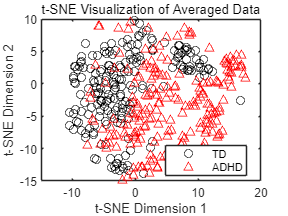

figure;
gscatter(tsne_averaged(:,1), tsne_averaged(:,2), labels, 'kr', 'o^');
title('t-SNE Visualization of Averaged Data');
legend('TD', 'ADHD');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');